# Calculate when the International Space Station is closest to Natick, MA USA

Quickly visualize the location of the satellite for the next 2 hours

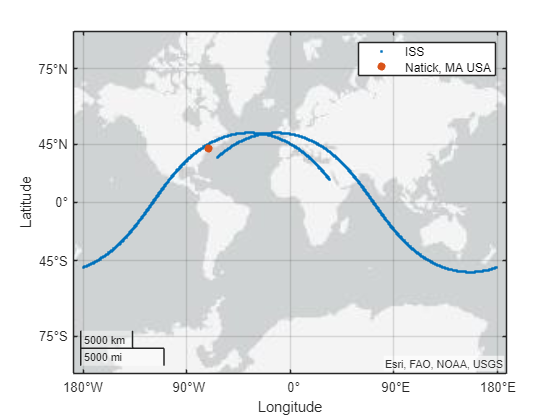

loc = nextnhours("./data/iss.txt", 2);
geoscatter(loc(:, 1), loc(:, 2), ".")
hold on
% location of Natick, MA USA
geoscatter(42.2775, -71.3468, "filled")
hold off
legend("ISS", "Natick, MA USA")

## Task 1

The function `nextnhours` has two inputs: a file containing orbital parameters of a satellite and the number of hours to track its location. To use this function with `fminbnd`, it must have only one scalar input.

nnhISS = @(n) nextnhours("./data/iss.txt", n);

## Task 2

Now that you have an interface with a single scalar input, you need to modify the output to be a scalar that gives the distance. The distance formula is

*D*=√(Lat*n*−LatNat)^2+(Lon*n*−LonNat)^2

where (*L**a**t**n*,*L**o**n**n*) are the latitude and longitude coordinates of the satellite after `n` hours, and (*L**a**t**N**a**t*,*L**o**n**N**a**t*) are the coordinates of Natick.

When called with a single output, `nnhISS` outputs a matrix just like `nextnhours`. The latitude at hour `n` is the last element of the first column, and the corresponding longitude is the last element of the second column.

dist = @(M) sqrt((M(end, 1)-42.2775)^2+(M(end, 2)-(-71.3468))^2)

dist = function_handle with value:
    @(M)sqrt((M(end,1)-42.2775)^2+(M(end,2)-(-71.3468))^2)


## Task 3

satDist = @(n) dist(nnhISS(n))

satDist = function_handle with value:
    @(n)dist(nnhISS(n))


## Task 4

Find when the satellite is closest to Natick using `fminbnd`. The syntax for `fminbnd` is

`fminbnd``(``fun``,``x1``,``x2``)`

where `fun` is a function name that will be minimized between `x1` and `x2`.

whenClosest = fminbnd(satDist, 0, 1.5)

whenClosest = 0.0047

# Track location of satellite for next `n` hours

`file` is a character vector or string containing the filename of satellite parameters

`n` is the number of hours for which to track the satellite

Two optional `Name,Value` pairs are

- `StartTime`

- `Frequency`

`[lat,lon]`  are the latitude and longitude of the satellite.  If one output is requested, the latitude and longitude are returned as the first and second columns of a single matrix.

## Examples

`[lat,lon] = nextnhours(``"iss.txt"``,0.5);`

`loc = nextnhours(``"iss.txt"``,0.5);`

function [lat,lon] = nextnhours(file,n)
    %Set default value of n if not given
    if nargin < 2
        n = hours(1);
    end
    
    % Check type of n
    if isnumeric(n)
        n = hours(n);
    end
    
    % Build vector of times
    tstart = datetime('now');
    tend = tstart + n;
    dt = seconds(10);
    t = (tstart:dt:tend)';
    
    % Get satellite positions
    [lat,lon] = satelliteposition(file,t);
    
    % Determine form of output (from number of outputs requested)
    if nargout < 2
        lat = [lat lon];
    end
end

# Calculate latitude and longitude of satellite

Determines (ECF) position of a satellite at a given time.

`[lat,lon] = satelliteposition(params,t)` calculates the latitude (`lat`) and longitude (`lon`), in Earth-centered fixed coordinates, of a satellite defined by the orbital parameters in the structure params for each time in the datetime array `t`.  The variable `params` can also be a file containing the parameters.

## Examples

`[lat,lon] = satelliteposition(params,t);`

`[lat,lon] = satelliteposition(file,t);`

function [lat,lon] = satelliteposition(params,t)

if ~isstruct(params)
    % Get parameters from file
    params = readparameters(params);
end

% Extract parameters
inc = params.inclination;  % Inclination [deg]
e = params.eccentricity;   % Eccentricity []
n = params.motion;         % Mean Motion [rev/day]

% Semi-major axis
a = (2.975541313977700e+015/(2*pi*n)^2)^(1/3); % Constant is G*M_Earth

% Constant for converting between degrees and radians
rd = 180/pi;

t = date2julian(t);
% Calculate time since epoch
dt = t - params.epoch;
% Number of rotations since epoch time
ndt = n*dt;
% Current mean anomaly (Mt0 + fractional part of ndt)
M = mod(params.anomaly + 360*(ndt - floor(ndt)),360)/rd;
% Solve Kepler's equation to get eccentric anomaly
E = M;
f = e*sin(E) + M;
while norm(E-f) > 1e-6
    E = f;
    f = e*sin(E) + M;
end
% Calculate true anomaly
nu = 2*rd*atan2(sqrt((1+e)/(1-e))*sin(E/2),cos(E/2));

% Account for precession of orbit (RAAN and Arg of Perigee)
[aWt,wt] = precession(a,e,inc,ndt,params.RAAN,params.argPerigee);
% Argument of Latitude
mu = mod(wt + nu,360);
% Difference in RA between satellite's geocentric position and RAAN
Da = acosd(cosd(mu) ./ sqrt(1-sind(inc)^2*sind(mu).^2));
idx = ((inc < 90) & (mu > 180)) | ((90 < inc) & (180 > mu));
Da(idx) = 360 - Da(idx);

% Geocentric coordinates (RA and DEC)
ag = mod(aWt + Da,360);
dg = sign(sind(mu)).*acosd(cosd(mu)./cosd(Da));

% Radial distance
r = a*(1-e^2)./(1+e*cosd(nu));

lat = dg;
% Get longitude by shifting by Greenwich ST (then wrap to [-180 180])
lon = mod(ag - 15*mod(18.697374558 + 24.06570982441908*t,24) + 180,360) - 180;
end

function p = readparameters(fname)
% Get raw text from file; split into two lines
txt = strsplit(fileread(fname),'\n');

% Extract epoch year
ey = str2double(txt{1}(19:20));
% Convert 2-digit epoch year to 4-digit year
% (00-60 -> 2000-2060, 61-99 -> 1961-1999)
ey = 1900 + ey + 100*(ey < 60);
% Extract epoch day
ed = str2double(txt{1}(21:32));

% Build output structure
p.epoch = date2julian(datetime(ey,1,1) + days(ed - 1));

p.inclination = str2double(txt{2}(9:16));
p.RAAN = str2double(txt{2}(18:25));
p.eccentricity = str2double(['0.',txt{2}(27:33)]);
p.argPerigee = str2double(txt{2}(35:42));
p.anomaly = str2double(txt{2}(44:51));
p.motion = str2double(txt{2}(53:63));

end

function [aWt,wt] = precession(a,e,inc,ndt,aW,w)
% Determines effects of precession on satellite location
%
% [AWT,WT] = PRECESSION(A,E,I,NDT,AW,W) calculates the right ascension of
% the ascending node and the argument of perigee for the satellite due to
% precession. A is the semi-major axis, E is the eccentricity, I is the
% inclination, NDT is the number of rotations since epoch, aW is the
% original value for the right ascension of the ascending node and w is the
% original argument of perigee.
aE = 1;
a1 = a/6378.135;
J2 = 1.082616e-3;
d1 = (3*J2*aE^2*(3*cosd(inc)^2 - 1))/(4*a1^2*(1-e^2)^(3/2));
a0 = -a1*(134*d1^3/81 + d1^2 + d1/3 - 1);
p0 = a0*(1-e^2);
aWt = aW + 360*(-3*J2*aE^2*ndt*cosd(inc) / (2*p0^2));
wt = w + 360*(3*J2*aE^2*ndt*(5*cosd(inc)^2 - 1)/(4*p0^2));
end

function tjulian = date2julian(t)
tjulian = days(t - datetime(2000,1,1,12,0,0));
end